clear all
close all
clc
path = 'InvestmentReplica.mat';
load(path)
Date_ME = XTab.Date(:, :);

## 1. Data collection and objective

Construct a Monster Index to be replicated.

% Synthetic target weights
wHFRXGL = 0.33; 
wMXWO = 0.33;
wLEGATRUU = 0.33;

% Building the target
y = wHFRXGL*price2ret(HFRXGL) + wMXWO*price2ret(MXWO) + wLEGATRUU*price2ret(LEGATRUU); % "Monster Index" returns
target = ret2price(y); % "Monster Index" levels

Check stationarity of the returns

CheckStationarity(y)

    The series is stationary


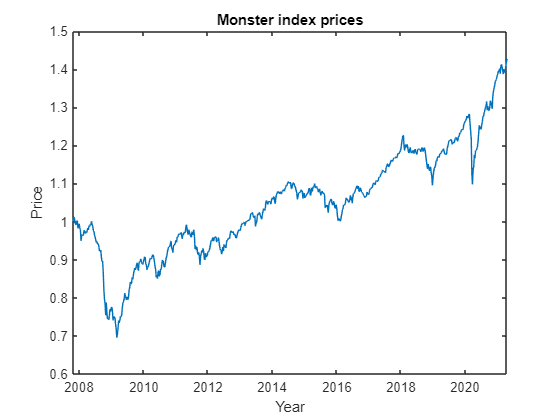

figure
plot(Date_ME,target)
xlabel('Year')
ylabel('Price')
title('Monster index prices')

Set of available future for replication.

% Futures returns
Futures = [CO1 DU1 ES1 GC1 LLL1 NQ1 RX1 TP1 TU2 TY1 VG1];
X = price2ret(Futures);

for i = 1:size(X,2)
    display(['For the Future: ',num2str(i)])
    CheckStationarity(X(:,i))
end

For the Future: 1


    The series is stationary


For the Future: 2


    The series is stationary


For the Future: 3


    The series is stationary


For the Future: 4


    The series is stationary


For the Future: 5


    The series is stationary


For the Future: 6


    The series is stationary


For the Future: 7


    The series is stationary


For the Future: 8


    The series is stationary


For the Future: 9


    The series is stationary


For the Future: 10


    The series is stationary


For the Future: 11


    The series is stationary


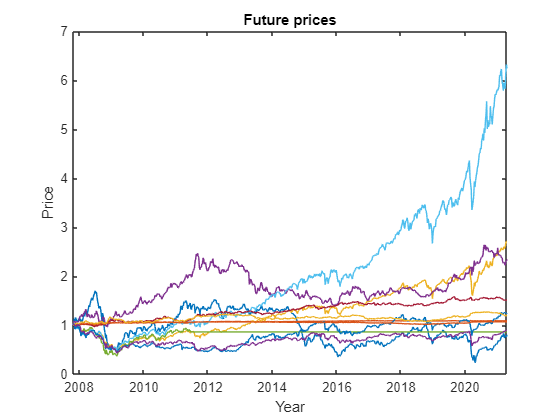

figure
plot(Date_ME,ret2price(X))
xlabel('Year')
ylabel('Price')
title('Future prices')

Define the dimensionalities. 

% Load the return data
portfolioReturns = y;
futuresReturns = X;

n = size(portfolioReturns, 1);  % Number of time steps
m = size(futuresReturns, 2);    % Number of futures

## 2. Construction of a Regression benchmark

We study the classical Regression methods: 

- Lasso 

- Ridge (alpha = 0)

- Elastic Net (alpha in (0,1) ) 

We consider only the two main lambda factor and not any intermediate one. 

In this section we focus just on minimizing the TEV value indipendently of the number of non-zero weights.

A possible alternative, more relevant when using more replicating idex, could have been to minimize the TEV and the number of non-zero weights.In that case it could have combined with a covariance analysis of the indexes to reduce their number.

Applying a Lasso regression
Optimizing using lambda such that MSE is min
The replication portfolio has TEV = 0.028545 and the following weights:


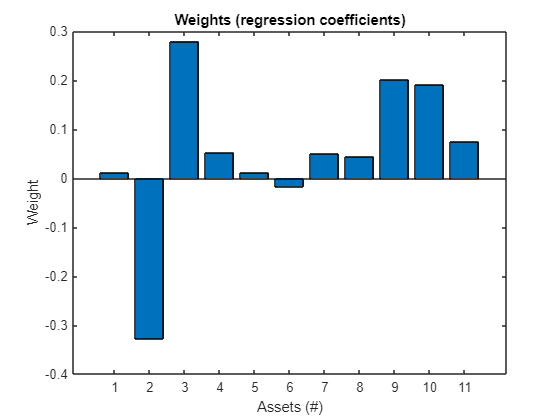

% In running this line it is possible to observe that the regression is not
% stable: sometimes the best fit is Lasso and other times is Elastic Net. 
% The change depends on how the code decide to apply the cross-validation on the 5
% folds. 
% We run it different times and decided to take Lasso as the best 
% (in the presentation we compare it to Ridge because it is the drastic
% opposite result)
RegressionResponse = RegressionReplication(X,y);

For what said above, to have a more coherent code we saved the RegressionResponse in the case of Lasso.

load RegressionResponse.mat
RegressionResponse

RegressionResponse = struct with fields:
           TEV: 0.0285
         alpha: 1
        lambda: 1
             b: [11×1 double]
       Returns: [704×1 double]
          Type: 'Lasso'
    lambdaType: 'IndexMinMSE'


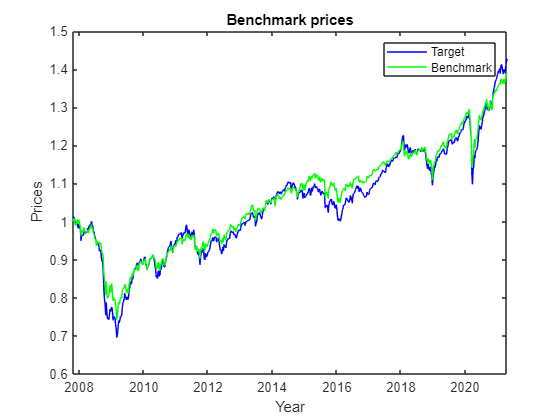

Benchmark = RegressionResponse.Returns;

figure()
plot(Date,ret2price(y),'Color','b')
hold on
plot(Date,ret2price(Benchmark),'Color','g')
legend('Target','Benchmark')
xlabel('Year')
ylabel('Prices')
title('Benchmark prices')

## 3. Application of the Kalman algorithm

Compute the weekly weights with Kalman-Filter.

Values for V1 and V2 are chosen based on the case we are considering. The model is quite sensible to their choice.

% y = portfolioReturns; (already done above)
% F = eye(m) so it can be omitted
% G = zeros(m) so the associated term is removed
H = futuresReturns;
% D = 0 so the associated term is removed
V1 = eye(m).*std(futuresReturns); 
V2 = std(portfolioReturns); 
% V12 = 0 so the associated term is removed

model = InitializeModel(y, [], [], H, [], V1, V2, []);

### Different calibration attempts

####     1. Empirically determine an actual solution for time t_0

TEV Kalman = 0.020639
TEV Benchmark = 0.028545


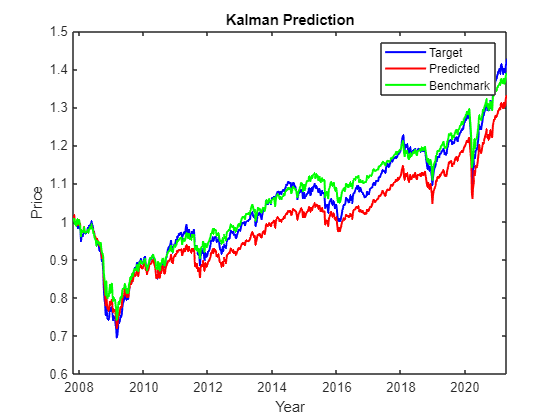

x_initial = ones(m,1)*0.065; % empirically obtained, intuitive best solution
[Weights,TEV_return] = mainKalman(model,x_initial,futuresReturns,Date_ME,Benchmark);

####     2. Try an almost random combination of weights

TEV Kalman = 0.032792
TEV Benchmark = 0.028545


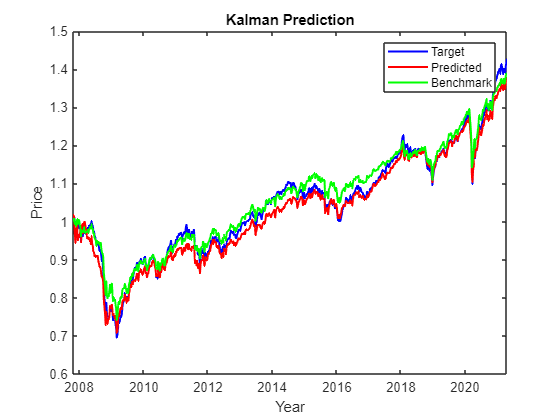

x_initial_temp = [-1/3 1/2 0 1/2 1/3 0 1/3 1/2 -1 1/2 -1/3]'; % to try with different initial values
[Weights_temp,TEV_return_temp] = mainKalman(model,x_initial_temp,futuresReturns,Date_ME,Benchmark);

####     3. Uniform weights

TEV Kalman = 0.021184
TEV Benchmark = 0.028545


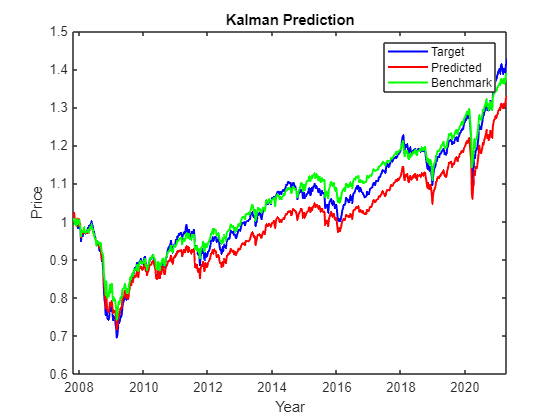

x_initial_temp = ones(m,1)/11; % to try with different initial values
[Weights_temp,TEV_return_temp] = mainKalman(model,x_initial_temp,futuresReturns,Date_ME,Benchmark);

### Statistical measures

Prediction = sum(X.*Weights',2);

% Gross Total Return, and Excess Return (ER)
logRClone = diff(log(ret2price(Prediction))); 
logRTarget = diff(log(ret2price(y)));
logTE =  logRClone - logRTarget;
meanTRTarget = exp(mean(logRTarget)*52) - 1;
meanTRClone = exp(mean(logRClone)*52) - 1;
meanER = exp(mean(logTE)*52) - 1;
IR = meanER/TEV_return;

display(['IR = ',num2str(IR)])

IR = -0.17984


% R-squared
% Compute the residual sum of squares (RSS)
RSS = sum((y - Prediction).^2);
% Compute the total sum of squares (TSS)
TSS = sum((y - mean(y)).^2);
% Compute R-squared
R_squared = 1 - RSS / TSS;

display(['R^2 = ',num2str(R_squared)])

R^2 = 0.92068


## 4. Cost considerations

### 4.1 Different time weight modification

Actual cost of transaction.  It is assumed to be a fixed price of 5$ for each transaction, indipendently of the quantity selled or buyed but just of the open transaction. 

CostTransaction = 5;

### Weekly modifications

Prediction_1 = sum(futuresReturns.*Weights',2);
TEV_return_week = ComputeTEV(Prediction_1,y)

TEV_return_week = 0.0206

Total cost for weekly change the weights

Total_Cost_weekly = ComputeCost(Weights,CostTransaction)

Total_Cost_weekly = 30635

Average week cost for weekly change the weights

Cost_PerWeek_week = Total_Cost_weekly/size(Weights, 2)

Cost_PerWeek_week = 43.5156

### Monthly modifications

Weights constant in the month. 

Weights_monthly = Weights;
num_month = 1;
for i = 2:n
    if month(Date_ME(i)) == month(Date_ME(i-1))
        Weights_monthly(:,i) = Weights_monthly(:,i-1);
    else
        Weights_monthly(:,i) = Weights_monthly(:,i);
        num_month = num_month+1;
    end
end

Prediction_1 = sum(futuresReturns.*Weights_monthly',2);
TEV_return_month = ComputeTEV(Prediction_1,y)

TEV_return_month = 0.0296

Total cost for monthly change the weights

Total_Cost_monthly = ComputeCost(Weights_monthly,CostTransaction)

Total_Cost_monthly = 8050

Average week cost for monthly change the weights

Cost_PerWeek_month = Total_Cost_monthly/size(Weights, 2)

Cost_PerWeek_month = 11.4347

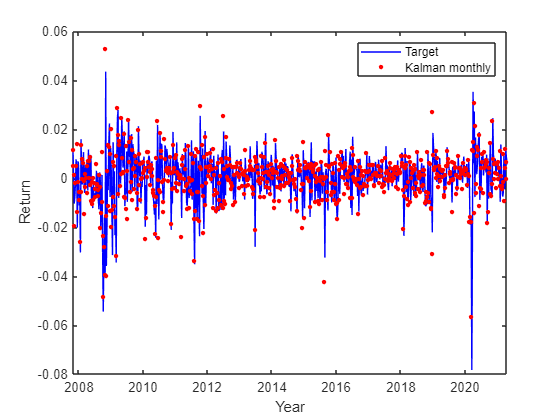

figure()
plot(Date_ME(2:end),y,'Color','b')
hold on
plot(Date_ME(2:end),sum(futuresReturns.*Weights_monthly',2),'r.','MarkerSize',10)
legend('Target','Kalman monthly')
xlabel('Year')
ylabel('Return')

### Yearly modifications

Weights constant in the year.

Weights_yearly = Weights;
num_year = 1;
for i = 2:n
    if year(Date_ME(i)) == year(Date_ME(i-1))
        Weights_yearly(:,i) = Weights_yearly(:,i-1);
    else
        Weights_yearly(:,i) = Weights_yearly(:,i);
        num_year = num_year+1;
    end
end

Prediction_1 = sum(futuresReturns.*Weights_yearly',2);
TEV_return_year = ComputeTEV(Prediction_1,y)

TEV_return_year = 0.0325

Total cost for yearly change the weights

Total_Cost_yearly = ComputeCost(Weights_yearly,CostTransaction)

Total_Cost_yearly = 800

Average week cost for yearly change the weights

Cost_PerWeek_year = Total_Cost_yearly/size(Weights, 2)

Cost_PerWeek_year = 1.1364

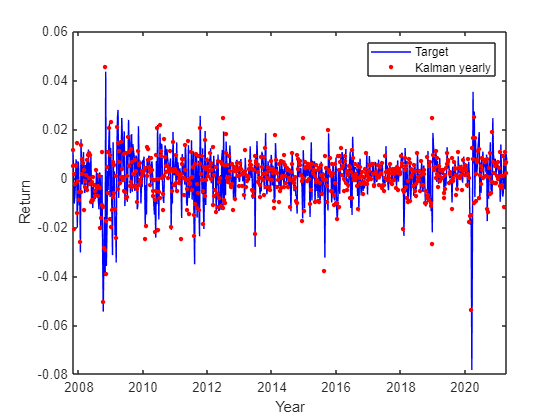

figure()
plot(Date_ME(2:end),y,'Color','b')
hold on
plot(Date_ME(2:end),sum(futuresReturns.*Weights_yearly',2),'r.','MarkerSize',10)
legend('Target','Kalman yearly')
xlabel('Year')
ylabel('Return')

### 4.2 Cost-Benefit analysis

Cost-benefit analysis with 1 week, 1 month and 1 year.

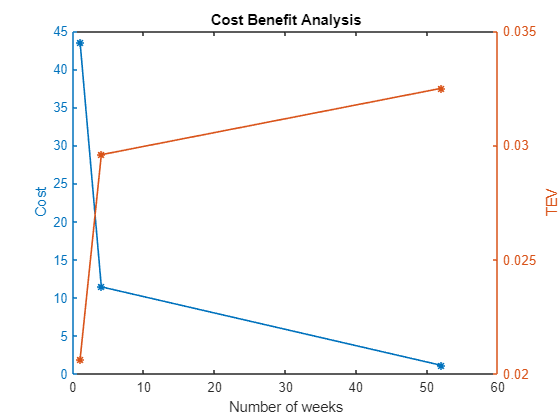

costs = [Cost_PerWeek_week, Cost_PerWeek_month, Cost_PerWeek_year];
TEVs = [TEV_return_week, TEV_return_month, TEV_return_year];

xgrid = [1 4 52]; % 1 week, 1 month (4 weeks), 1 year (52 weeks)

figure()
yyaxis left
plot(xgrid,costs,'-*','LineWidth',1.2);
hold on
ylabel('Cost')

yyaxis right
plot(xgrid,TEVs,'-*','LineWidth',1.2);
hold on
ylabel('TEV')
xlabel('Number of weeks')
title('Cost Benefit Analysis')

Interesection between TEV and costs. 

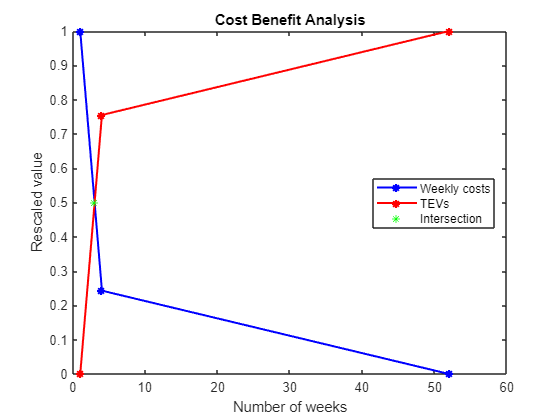

costs_rescale = rescale(costs);
TEVs_rescale = rescale(TEVs);

% To run this line is required to install the add-on: "Curve Intersection"
% NS (2023). Curve intersections (https://www.mathworks.com/matlabcentral/fileexchange/22441-curve-intersections), 
% MATLAB Central File Exchange. Retrieved May 24, 2023.
P = InterX([xgrid;costs_rescale],[xgrid;TEVs_rescale]);
figure()
plot(xgrid, costs_rescale, "-b*", "linewidth", 1.5)
hold on 
plot(xgrid, TEVs_rescale, "-r*", "linewidth", 1.5)
plot(P(1),P(2),"g*")
xlabel('Number of weeks')
ylabel('Rescaled value')
title("Cost Benefit Analysis")
legend("Weekly costs", "TEVs", "Intersection", Location="best")

### 4.3 Studying the optimal intersection

#### 3 weeks modifications

Weights_3weeks = Weights;

for i = 1:3:n
    for j = 0:2
        Weights_3weeks(:,i+j) = Weights_3weeks(:,i);    
    end
end

Prediction_1 = sum(futuresReturns.*Weights_3weeks(:, 1:end-1)',2);
TEV_return_3weeks = ComputeTEV(Prediction_1,y)

TEV_return_3weeks = 0.0284

Total cost for change the weights each 3 weeks

Total_Cost_3weeks = ComputeCost(Weights_3weeks,CostTransaction)

Total_Cost_3weeks = 11415

Average week cost for change the weights each 3 weeks

Cost_3weeks = Total_Cost_3weeks/size(Weights, 2)

Cost_3weeks = 16.2145

Cost-benefit analysis with 1 week, 3 weeks, 1 month and 1 year.

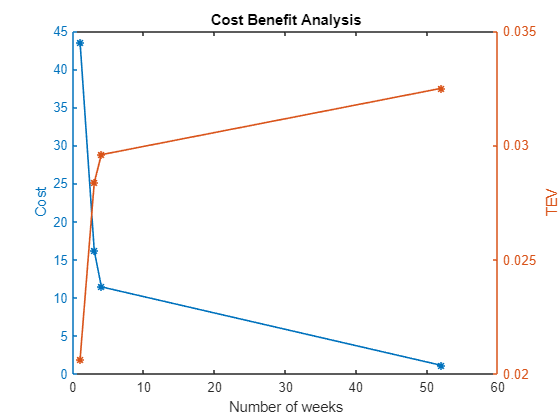

costs = [Cost_PerWeek_week, Cost_3weeks, Cost_PerWeek_month, Cost_PerWeek_year];
TEVs = [TEV_return_week, TEV_return_3weeks, TEV_return_month, TEV_return_year];

xgrid=[1,3,4,52]; % 1 week, 3 weeks, 1 month (4 weeks), 1 year (52 weeks)

figure()
yyaxis left
plot(xgrid,costs,'-*','LineWidth',1.2);
hold on
ylabel('Cost')

yyaxis right
plot(xgrid,TEVs,'-*','LineWidth',1.2);
hold on
ylabel('TEV')
xlabel('Number of weeks')
title('Cost Benefit Analysis')

Cost-benefit analysis compared with benchmark.

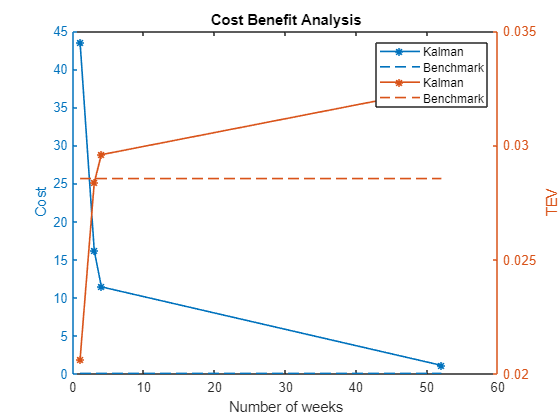

costs = [Cost_PerWeek_week, Cost_3weeks, Cost_PerWeek_month, Cost_PerWeek_year];
TEVs = [TEV_return_week, TEV_return_3weeks, TEV_return_month, TEV_return_year];

xgrid=[1,3,4,52]; % 1 week, 3 weeks, 1 month (4 weeks), 1 year (52 weeks)

figure()
yyaxis left
plot(xgrid,costs,'-*','LineWidth',1.2);
hold on
plot(xgrid,ones(4,1)*5*11/size(Weights, 2),'LineWidth',1.2);
ylabel('Cost')

yyaxis right
plot(xgrid,TEVs,'-*','LineWidth',1.2);
hold on
plot(xgrid,ones(4,1)*RegressionResponse.TEV,'LineWidth',1.2);
ylabel('TEV')
xlabel('Number of weeks')
title('Cost Benefit Analysis')
legend('Kalman','Benchmark','Kalman','Benchmark')

## 5. Conclusions

So, what do we conclude?

From a theoretical point of view the idea of using dynamical weights, given by an algorithm as the Kalman filter, is quite interesting. The strength of this procedure,in contrast to Lasso, Ridge or Elastic Net regression, lies in adapting the results to temporal trends, thanks to this we are able to grasp more clearly eventual market fluctuations.  

However the application to reality is not so meaningfull. First of all, the new approach is quite sensitive to the initial parameters and this can induce in high unpredictability on the result. This effect can reduce the capability of the model to be standardized and reused in different context. Moreover, dynamical weights, that in theory seems to be an excellent solution, require associated costs of transaction each time they are modified. 

We can conclude that, even if a regression model approach can be less precise (assuming to find a suffciently good calibration for the Kalmann filter) it is more robust and cost-effective.